# Rufous Robust Attitude and Angular Rate Controller with Multiplicative Input Uncertainty

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
ht = sqrt(g * mass / (Kt * 4));

RUFOUS_N_INPUTS = 4;			% number of inputs
RUFOUS_N_STATES = 6;			% number of states
RUFOUS_STATE_DIM = 3;			% dimension of each state

## Attitude Plant

I = eye(RUFOUS_STATE_DIM);
O = zeros(RUFOUS_STATE_DIM, RUFOUS_STATE_DIM);

tau_k = [1  0 -1  0;		% Alter this to effect the sensitivity of input -> state channels
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I;				    % block size (state_dim, state_dim)
	 O O];
B = Kt *[zeros(RUFOUS_STATE_DIM, RUFOUS_N_INPUTS); l * tau_k];		% block size (state_dim, n_inputs) ignore non-controlled forces
C = eye(RUFOUS_N_STATES);
D = 0;

G = ss(A, B, C, D);

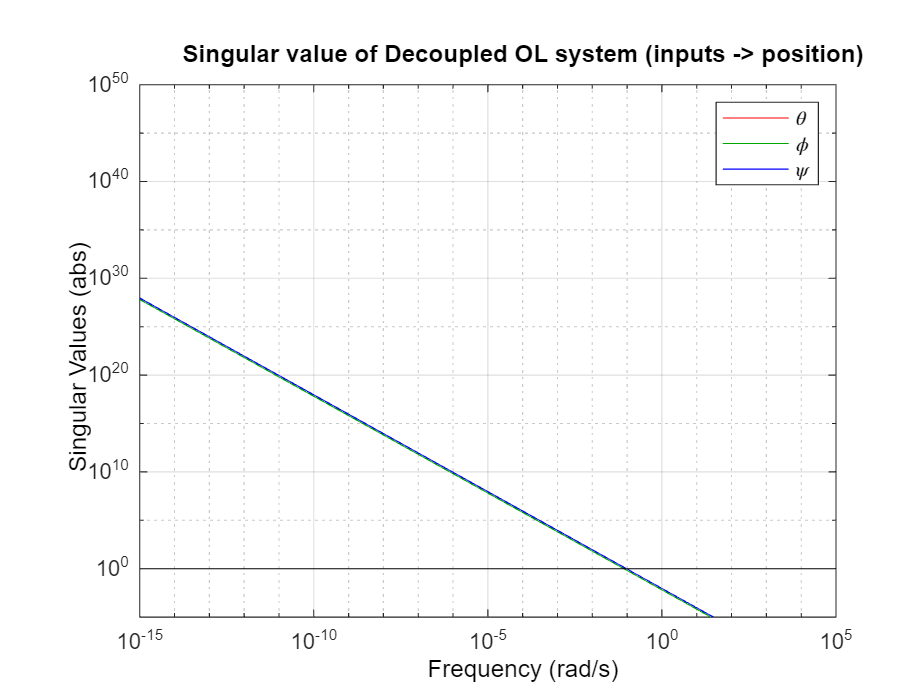

mag_range = [1e-5 1e50];
freq_range = [1e-15 1e5];

% Without a control law X and Y will not appear
figure, hold on, grid minor
h = sigmaplot(G(1, :), 'r', G(2, :), 'g', G(3, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> position)")
legend("\theta", "\phi", "\psi")

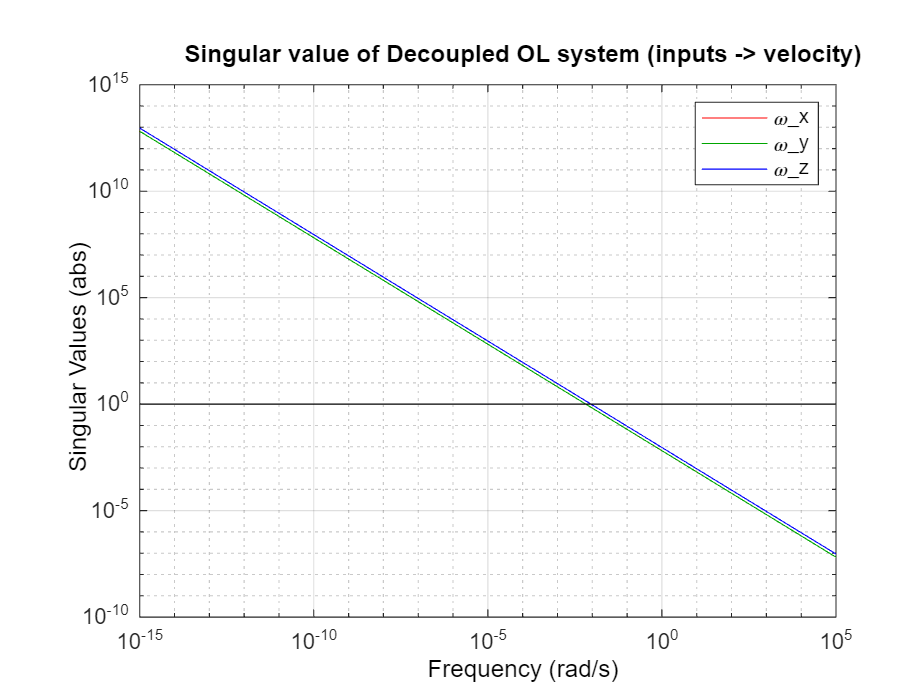


figure, hold on, grid minor
h = sigmaplot(G(4, :), 'r', G(5, :), 'g', G(6, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> velocity)")
legend("\omega_x", "\omega_y", "\omega_z")

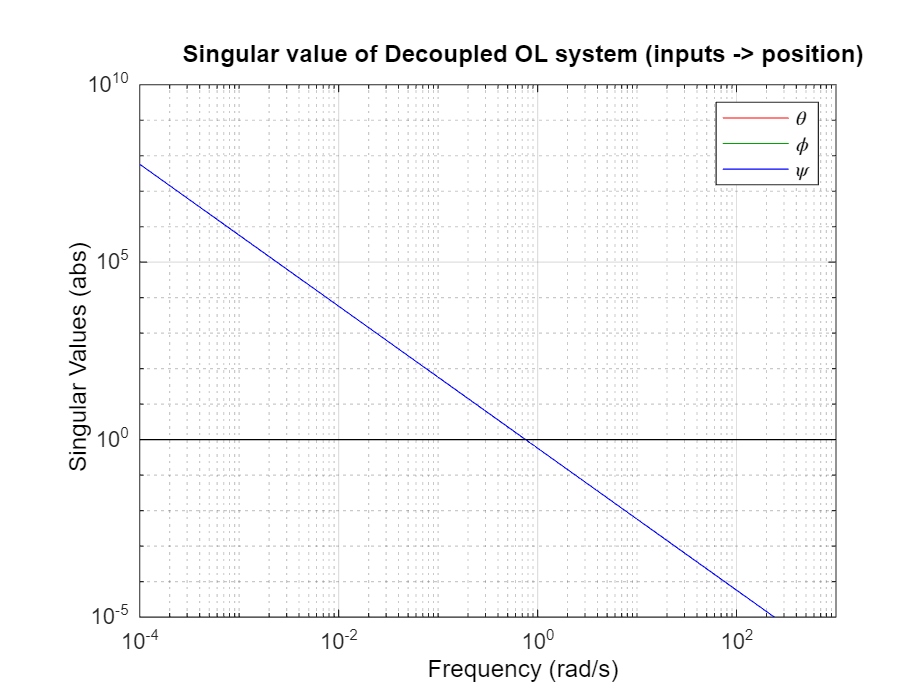

mag_range = [1e-2 1e4];
freq_range = [1e-4 1e3];

z = [0; 0; 1];
Z = [z z z z];
Xo = [0; 0; 0];
Uo = [0; 0; 0; 0];
Ht = [ht; ht; ht; ht];
I = eye(RUFOUS_STATE_DIM);
O = zeros(RUFOUS_N_INPUTS, RUFOUS_STATE_DIM);

% [Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 40, 75, 0.1, 1, 50);
[Kref, Kfb, ~] = Rufous_og_controller(Kt, mass, g, [0; 0; 0], 75, 100, 0.08, 0.5, 15);

K = ss(Kfb(:,7:end));
L = G * K;

% With a control law no X and Y
figure, hold on, grid minor
h = sigmaplot(L(1, :), 'r', L(2, :), 'g', L(3, :), 'b'); % 
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range) % , 'Ylim', mag_range
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> position)")
legend("\theta", "\phi", "\psi")

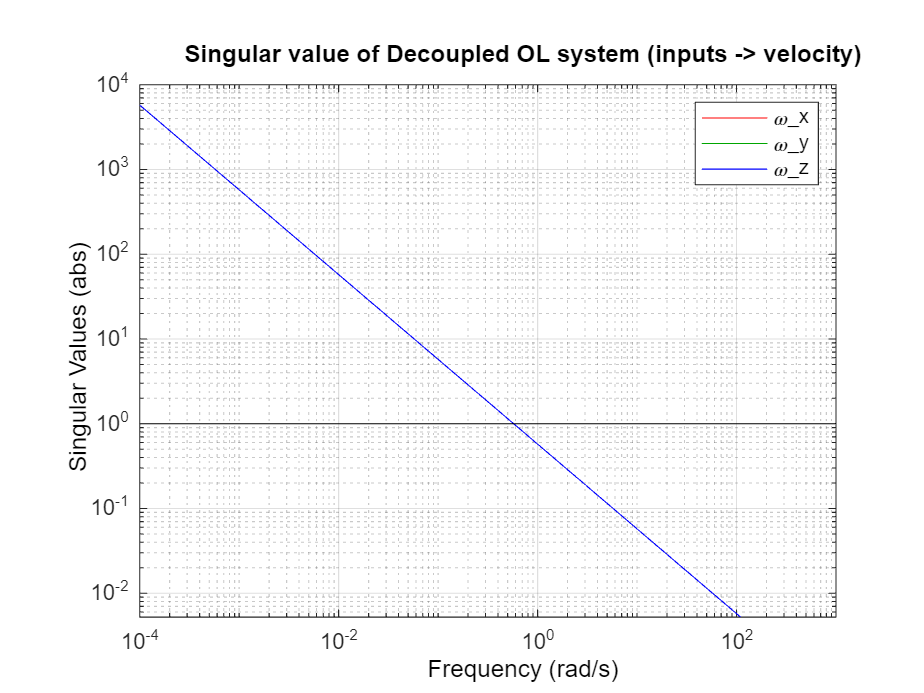


figure, hold on, grid minor
h = sigmaplot(L(4, :), 'r', L(5, :), 'g', L(6, :), 'b');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range)
plot(freq_range, [1, 1], 'k');
title("Singular value of Decoupled OL system (inputs -> velocity)")
legend("\omega_x", "\omega_y", "\omega_z")

mag_range = [1e-2 1e4];
freq_range = [1e-10 1e3];

% Test previously designed control law
Katt = 75 * pinv(tau_k);
Krate = 100 * pinv(tau_k);

K = ss([Katt Krate]);
L = G * K;
S = 1 / (eye(RUFOUS_N_STATES) + L);
T = minreal(L * S);

6 states removed.



WI = makeweight(0.01, [2, 1], 10) * eye(RUFOUS_N_STATES);
WP = makeweight(0.1, [1, 1], 100) * eye(RUFOUS_N_STATES);

Hinf_norm_s = norm(S, 'inf')

Hinf_norm_s = 2.4326

Hinf_norm_t = norm(T, 'inf')

Hinf_norm_t = Inf

Hinf_norm_n11 = norm(WI * T, 'inf')

Hinf_norm_n11 = Inf

Hinf_norm_n22 = norm(WP * T, 'inf')

Hinf_norm_n22 = Inf

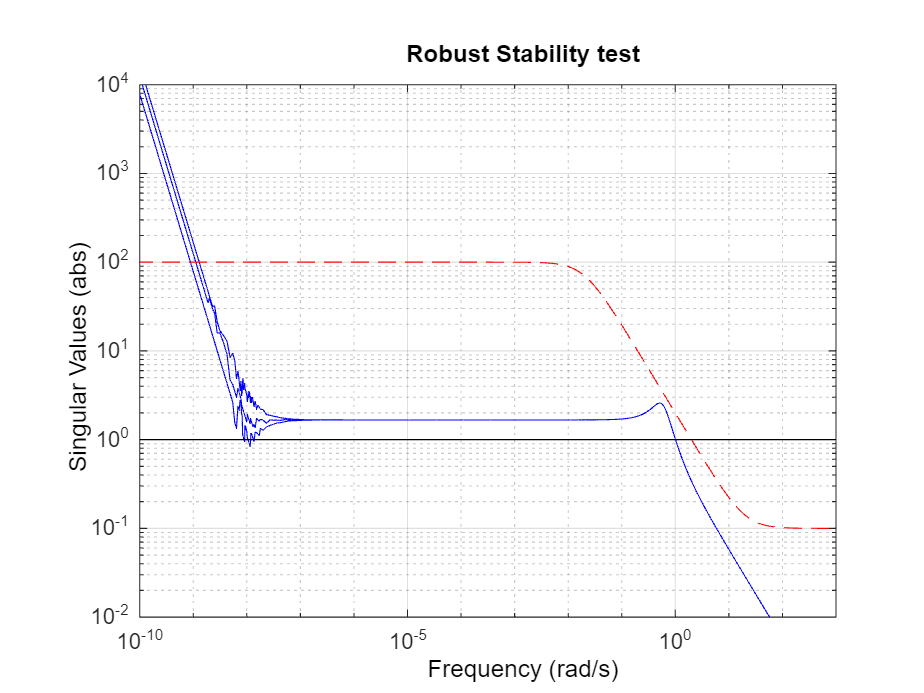


figure, hold on
h = sigmaplot(T, 'b', WI^-1, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range);
title("Robust Stability test")

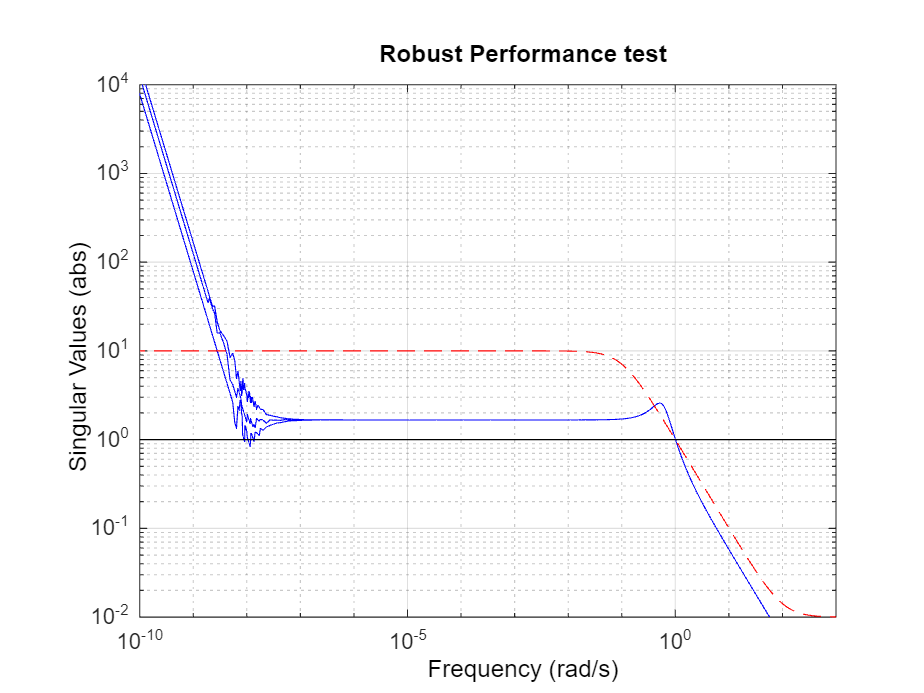


figure, hold on
h = sigmaplot(T, 'b', WP^-1, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'Xlim', freq_range, 'Ylim', mag_range);
title("Robust Performance test")

I = eye(RUFOUS_N_STATES);
O1 = zeros(RUFOUS_N_INPUTS, RUFOUS_N_STATES);
O2 = zeros(RUFOUS_N_STATES, RUFOUS_N_STATES);

WI = makeweight(0.01, [2, 1], 10) * eye(RUFOUS_N_INPUTS);
WP = makeweight(0.1, [1, 1], 100);

systemnames = 'G WP';
inputvar = '[qr(3); u(4)]';
outputvar = '[WP; qr-G]';
input_to_G = '[u]';
input_to_WP = '[]';
sysoutname = 'P';
sysic;

Error using sysic
There are an inconsistent number of signals in '+qr-G' portion of OUTPUTVAR.

P_nominal = minreal(ss(P))

[K, CL, GAM] = hinfsyn(P, 6, 4);